# HAMR SE2 Motion-planning

addpath 'Data'\ 'Utility Functions'\;
load('Data\HAMR6_SE2_kinematics.mat'); load('Data\HAMR6_SE2_kinematics_motionplan.mat');

## Trot Gait $S_{13} \leftrightarrow S_{24}$

### Translational sub-gait design in $S_{13}$

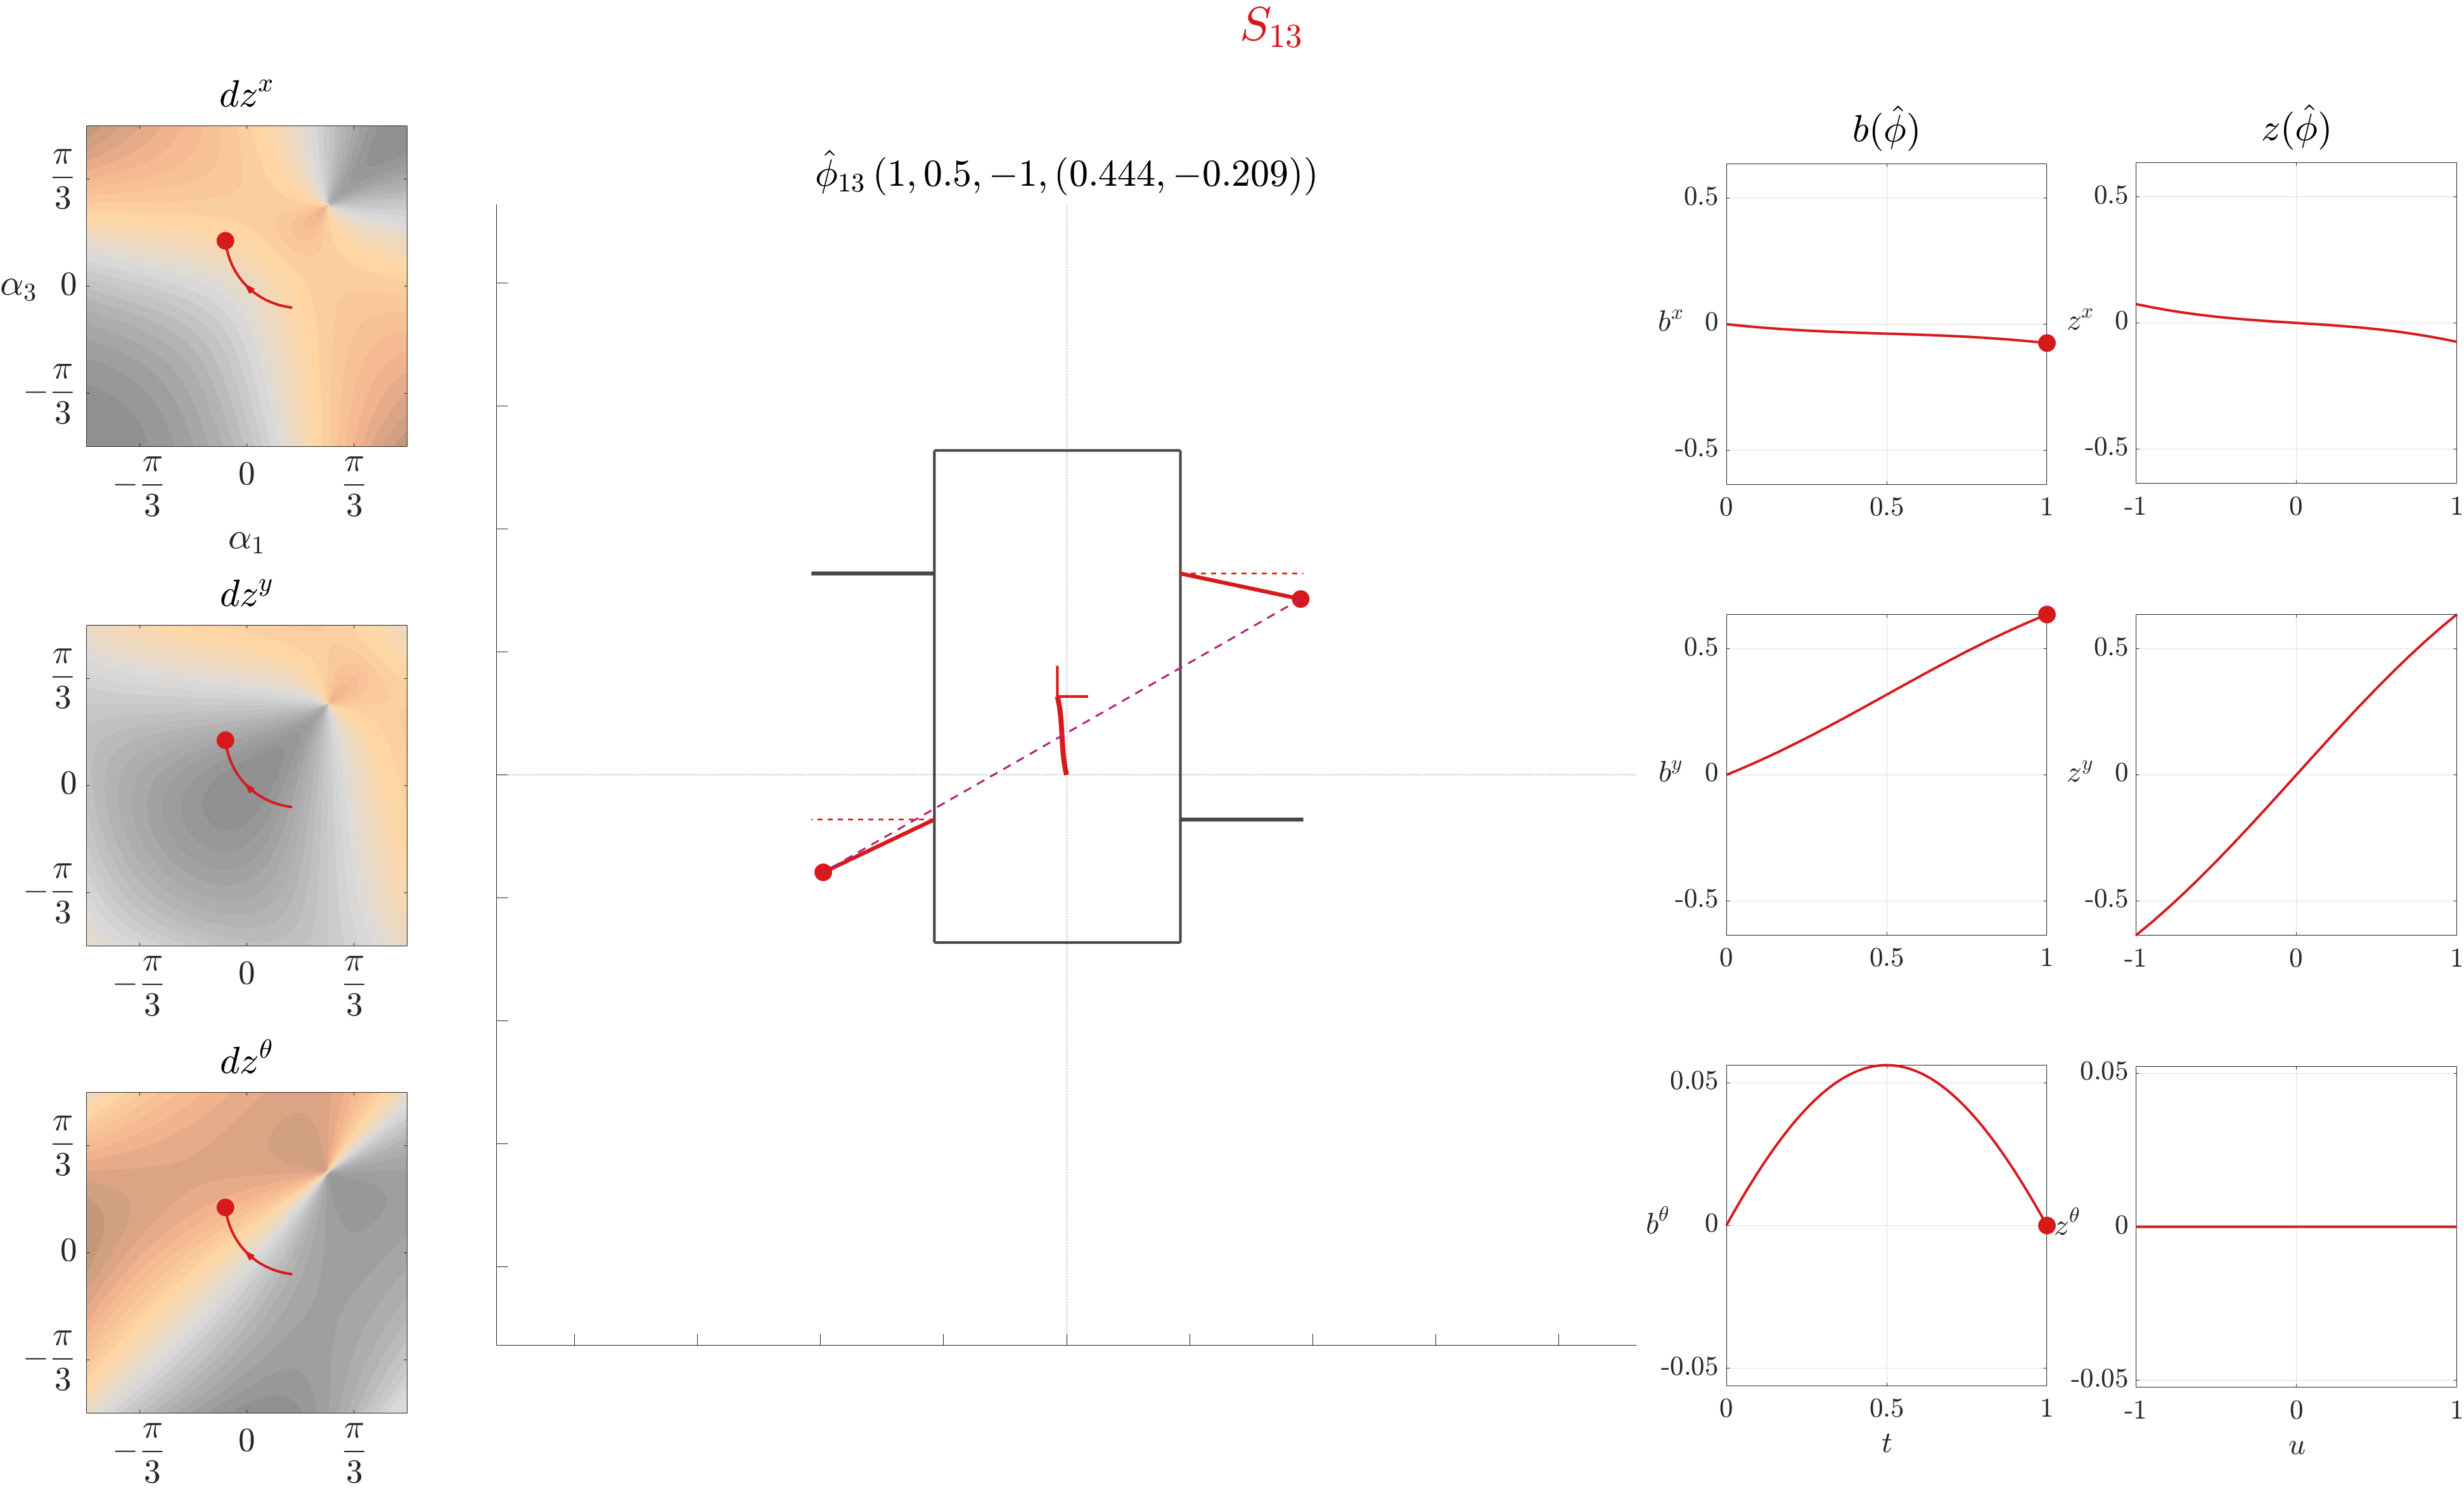

si = 5; % S13 % contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
% qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% conditions: "scale" or "slide"... 
% "scale" just scales the forward or backward path (increases translation), 
% "slide" slides the point of interest forward or backward (helps generate rotation)
% EVERYTHING IS IN THE CONTEXT OF TROT GAIT
u_mode = "scale"; S_data{1}.mode = u_mode; % for "trial" and "trans"
% u_mode = "slide"; S_data{1}.mode = u_mode; % for "steer" 
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = zeros(1, 2);
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [0.5, 0.5]; % trial
% t = [0.25, 0.25]; % trans & steer
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path13 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
switch u_mode
    case "scale"
        Path2.compute_trajectory( path13, symstr, dnum );
    case "slide"
        slide_mul = [2, 2]; % amount you cal slide by in [back, forw]
        Path2.compute_slide_trajectory( path13, symstr, dnum, slide_mul );
end
path = path13;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];  % for "trial" and "trans"
% S_data{1}.skp_path = [1 21]; % for "slide"
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% S13_HAMR_trial = S_data; 
% S13_HAMR_trans = S_data; 
S13_HAMR_steer = S_data; 
if exist('Data\HAMR6_S13_data.mat', 'file')
    % save('Data\HAMR6_S13_data.mat', 'S13_HAMR_trial', '-append');
    % save('Data\HAMR6_S13_data.mat', 'S13_HAMR_trans', '-append');
    save('Data\HAMR6_S13_data.mat', 'S13_HAMR_steer', '-append');
else
    % save('Data\HAMR6_S13_data.mat', 'S13_HAMR_trial');
    % save('Data\HAMR6_S13_data.mat', 'S13_HAMR_trans');
    save('Data\HAMR6_S13_data.mat', 'S13_HAMR_steer');
end
clear S_data;

addpath 'Data'\ 'Utility Functions'\;
load('Data\HAMR6_SE2_kinematics.mat'); load('Data\HAMR6_SE2_kinematics_motionplan.mat');

### Translational sub-gait design in $S_{24}$

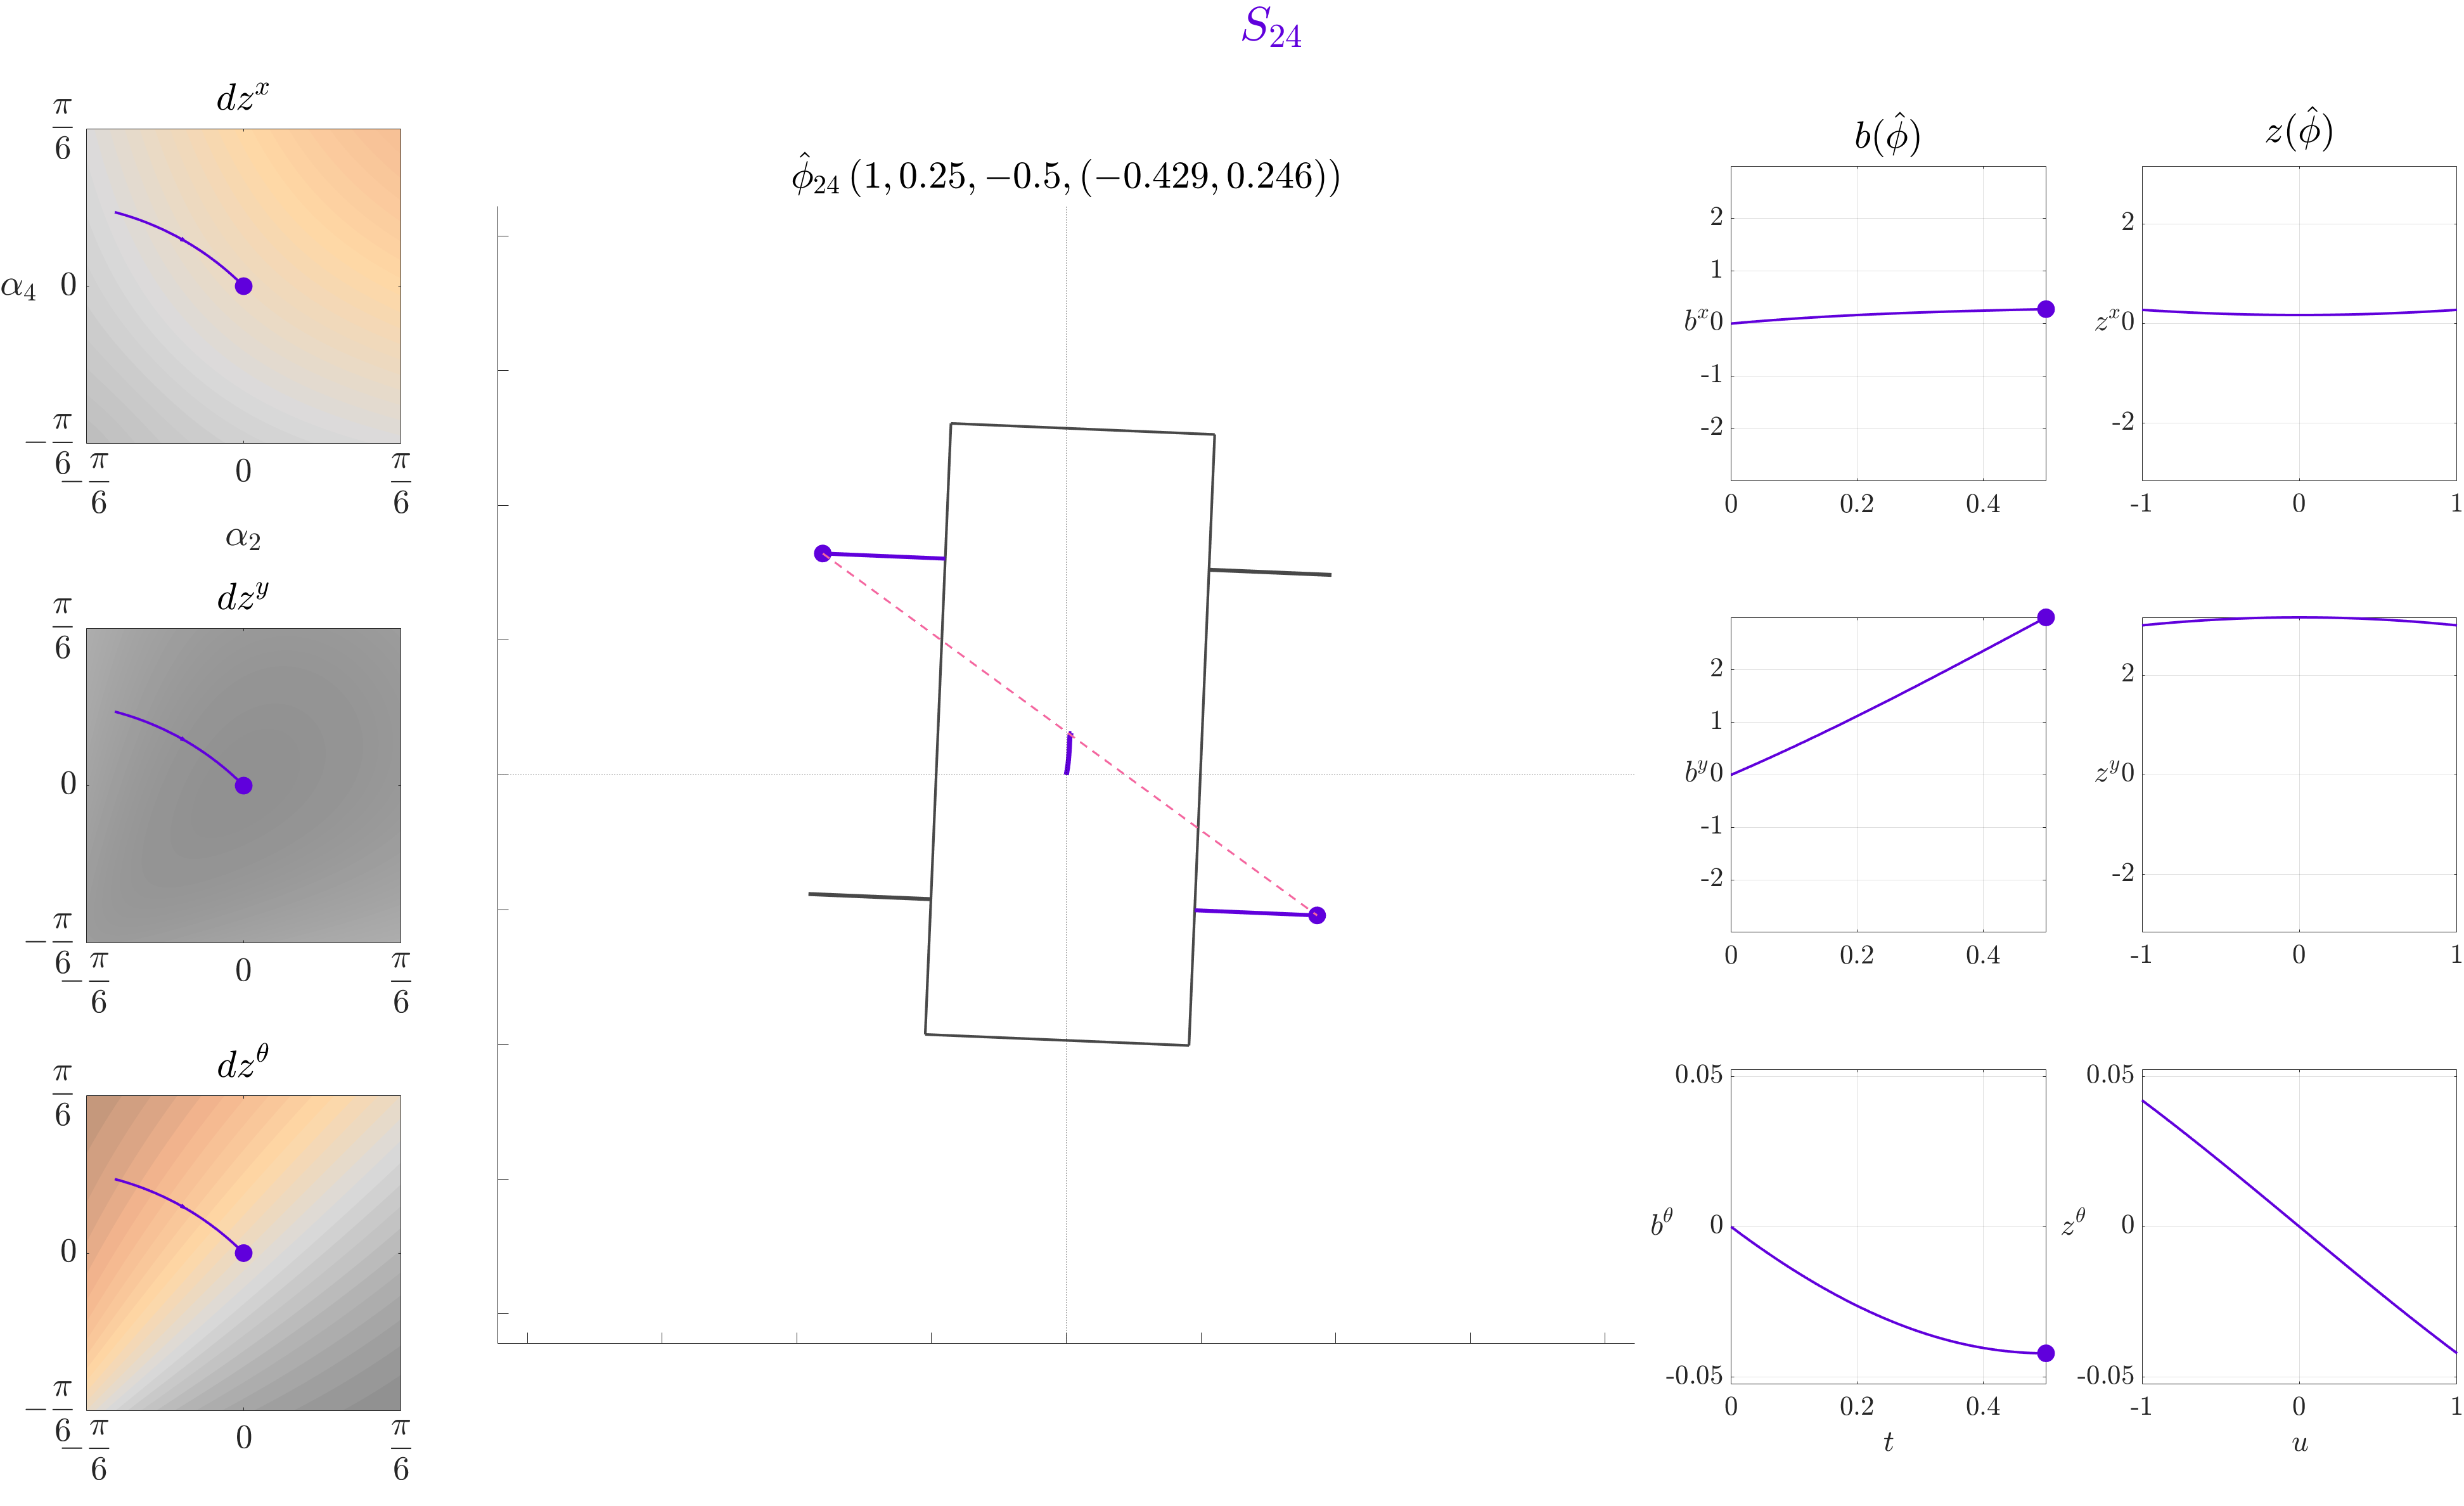

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 6; % S24
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
% qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% u_mode = "scale"; S_data{1}.mode = u_mode;
u_mode = "slide"; S_data{1}.mode = u_mode; % add it to plot information
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = zeros(1, 2);
%%%%%%%%%%%%%%%%%%%%%%%%%
% t = [0.5, 0.5]; % trial
t = [0.25, 0.25]; % trans
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = -1; % for "trial", "trans", and "steer"
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path24 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
switch u_mode
    case "scale"
        Path2.compute_trajectory( path24, symstr, dnum );
    case "slide"
        slide_mul = [2, 2];
        Path2.compute_slide_trajectory( path24, symstr, dnum, slide_mul );
end
path = path24;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20]; % for "trial" and "trans"
% S_data{1}.skp_path = [1 21]; % [1, 21] % for "steer"
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% S24_HAMR_trial = S_data;
% S24_HAMR_trans = S_data; 
S24_HAMR_steer = S_data; 
if exist('Data\HAMR6_S24_data.mat', 'file')
    % save('Data\HAMR6_S24_data.mat', 'S24_HAMR_trial', '-append');
    % save('Data\HAMR6_S24_data.mat', 'S24_HAMR_trans', '-append');
    save('Data\HAMR6_S24_data.mat', 'S24_HAMR_steer', '-append');
else
    % save('Data\HAMR6_S24_data.mat', 'S24_HAMR_trial');
    % save('Data\HAMR6_S24_data.mat', 'S24_HAMR_trans');
    save('Data\HAMR6_S24_data.mat', 'S24_HAMR_steer');
end
clear S_data;

addpath 'Data'\ 'Utility Functions'\;
load('Data\HAMR6_SE2_kinematics.mat'); load('Data\HAMR6_SE2_kinematics_motionplan.mat');
% load('Data\HAMR6_S13_data.mat', 'S13_HAMR_trial');
% load('Data\HAMR6_S24_data.mat', 'S24_HAMR_trial');
load('Data\HAMR6_S13_data.mat', 'S13_HAMR_trans');
load('Data\HAMR6_S24_data.mat', 'S24_HAMR_trans');
% load('Data\HAMR6_S13_data.mat', 'S13_HAMR_steer');
% load('Data\HAMR6_S24_data.mat', 'S24_HAMR_steer');

### 
$$S_{13} \leftrightarrow S_{24}$$


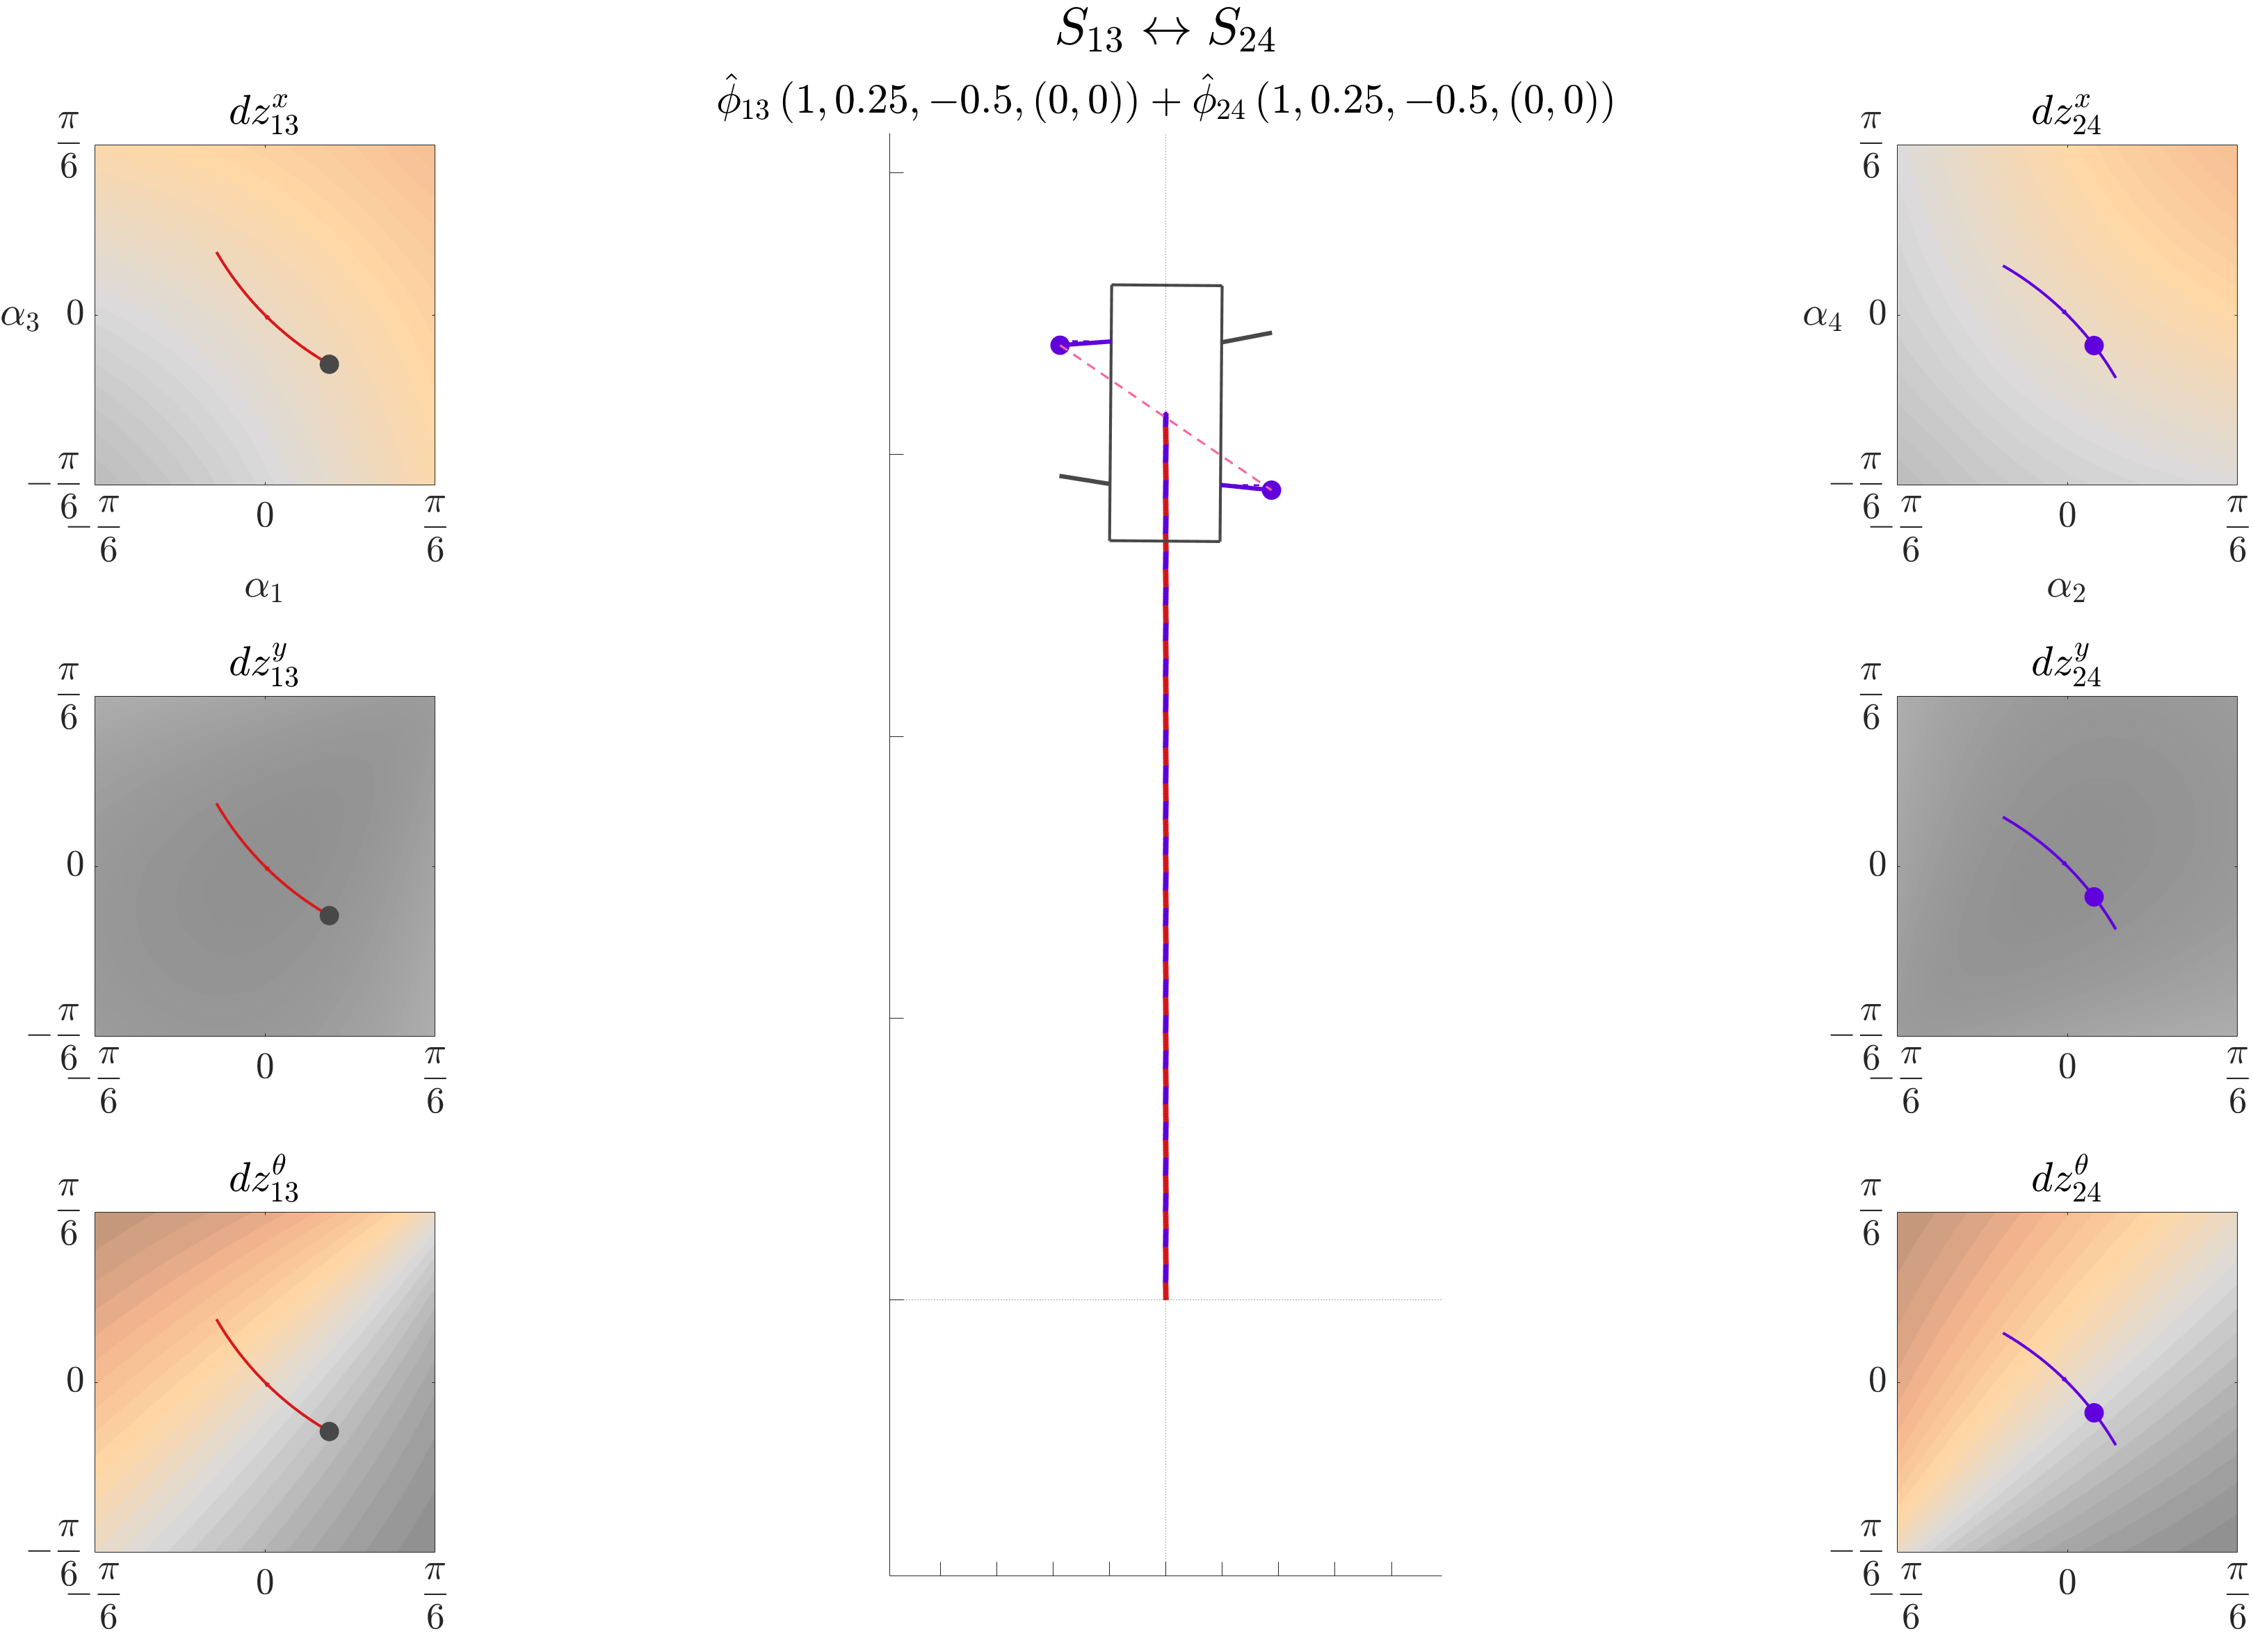

dataij = [];
dataij.vidF = false; % true % false
% dataij.u = [+100, +100]/100; dataij.gaitC_num = 25; % trial
dataij.u = [+100, +100]/100; dataij.gaitC_num = 25; % trans_1
% dataij.u = [-100, -100]/100; dataij.gaitC_num = 25; % trans_2
% dataij.u = [+100, -100]/100; dataij.gaitC_num = 25; % steer_1
% dataij.u = [-100, +100]/100; dataij.gaitC_num = 25; % steer_2
% S13_HAMR_trial{1}.fA = 0.7;
% S24_HAMR_trial{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_HAMR_trial, S24_HAMR_trial, dataij);
% plotnetdispofnoslip2bgaits(S13_HAMR_trial, S24_HAMR_trial, dataij);
S13_HAMR_trans{1}.fA = 0.7;
S24_HAMR_trans{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S13_HAMR_trans, S24_HAMR_trans, dataij);

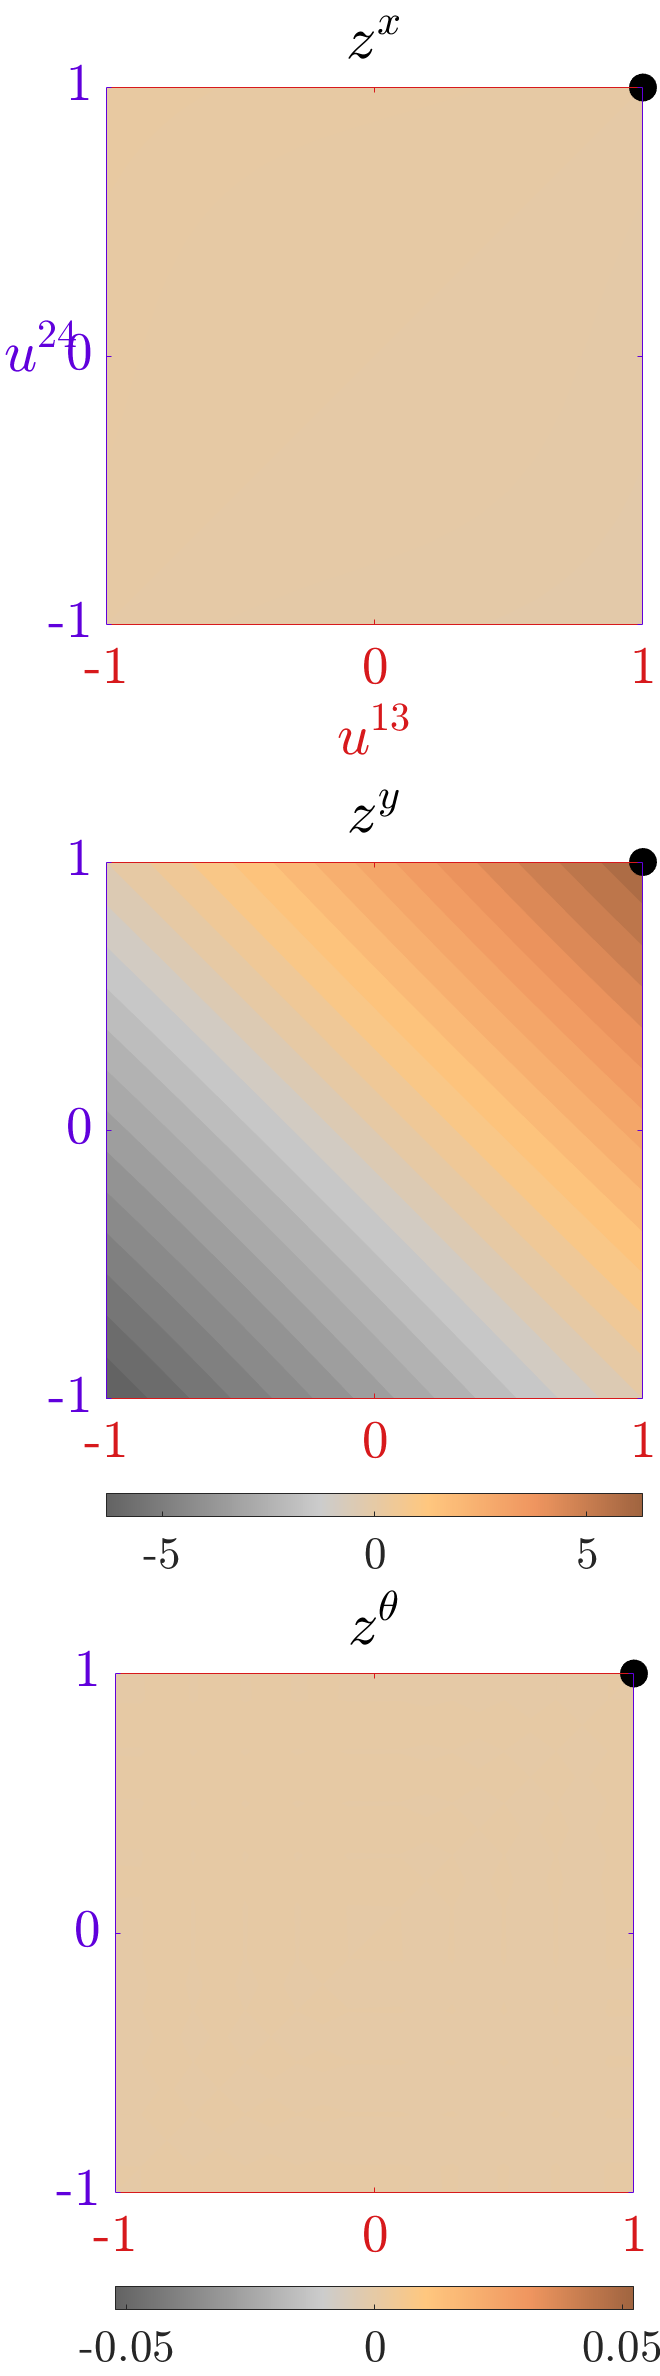

plotnetdispofnoslip2bgaits(S13_HAMR_trans, S24_HAMR_trans, dataij);

% S13_HAMR_steer{1}.fA = 0.7;
% S24_HAMR_steer{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_HAMR_steer, S24_HAMR_steer, dataij);
% plotnetdispofnoslip2bgaits(S13_HAMR_steer, S24_HAMR_steer, dataij);
% HAMR_S13toS24_trial_data = dataij;
HAMR_S13toS24_trans_1_data = dataij;
% HAMR_S13toS24_trans_2_data = dataij;
% HAMR_S13toS24_steer_1_data = dataij;
% HAMR_S13toS24_steer_2_data = dataij;
if exist('Data\HAMR6_S13toS24.mat', 'file')
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_trial_data', '-append');
    save('Data\HAMR6_S13toS24.mat', 'HAMR_S13toS24_trans_1_data', '-append');
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_trans_2_data', '-append');
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_steer_1_data', '-append');
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_steer_2_data', '-append');
else
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_trial_data');
    save('Data\HAMR6_S13toS24.mat', 'HAMR_S13toS24_trans_1_data');
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_trans_2_data');
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_steer_1_data');
    % save('Data\HAMR_S13toS24.mat', 'HAMR_S13toS24_steer_2_data');
end